% =====================================================================
% FxLMS 定点与浮点一致性验证（最终修正版）
% =====================================================================
clear; clc; close all;

%% 参数
L = 128; M = 5;
mu_float = -5e-6;                    % 负步长（适应负的次级路径增益）
s_hat_float = [0;0;0;0;-0.2];

% 量化格式
DATA_FRAC = 12; COEFF_FRAC = 16;
SHIFT_DELTA = 38;                    % 右移位数
MU_Q = round(mu_float * 2^SHIFT_DELTA);  % -1374390

% 量化函数
qdata = @(x) int16(round(x * 2^DATA_FRAC));
deq = @(x) double(x) / 2^DATA_FRAC;
qcoeff = @(x) int32(round(x * 2^COEFF_FRAC));

s_hat_q = qcoeff(s_hat_float);

%% 测试信号（确保在 Q4.12 范围内）
fs = 10000; duration = 2;
t = (0:fs*duration-1)'/fs;
x_phys = 5 * sin(2*pi*100*t);
d_phys = filter(s_hat_float, 1, x_phys);
x_q = qdata(x_phys);
d_q = qdata(d_phys);

%% 浮点基准
fprintf('浮点 FxLMS ...\n');

浮点 FxLMS ...


w_f = zeros(L,1);
xbuf_f = zeros(L+M,1);
xfbuf_f = zeros(L,1);
y_f = zeros(length(t),1);
for k = 1:length(t)
    if k >= L
        xbuf_f = [x_phys(k); xbuf_f(1:end-1)];
        xf = sum(s_hat_float .* xbuf_f(1:M));
        xfbuf_f = [xf; xfbuf_f(1:end-1)];
        y_f(k) = w_f' * xbuf_f(1:L);
        w_f = w_f - mu_float * d_phys(k) * xfbuf_f;
    end
end

%% 定点模型（精确匹配 FPGA）
fprintf('定点 FxLMS (Verilog 行为)...\n');

定点 FxLMS (Verilog 行为)...


w = zeros(L,1,'int32');
xbuf = zeros(L+M,1,'int16');
xfbuf = zeros(L,1,'int16');
y_fixed = zeros(length(t),1);

state = 0; cnt = 0; acc = int64(0); xf_reg = int16(0); y_reg = int16(0);

for k = 1:length(t)
    x_in = x_q(k);
    d_in = d_q(k);
    while true
        switch state
            case 0  % IDLE
                xbuf = [x_in; xbuf(1:end-1)];
                state = 1; cnt = 0; acc = int64(0);
            case 1  % COMP_XF
                if cnt < M
                    acc = acc + int64(s_hat_q(cnt+1)) * int64(xbuf(cnt+1));
                    cnt = cnt + 1;
                else
                    tmp = bitshift(acc, -COEFF_FRAC);
                    tmp = max(min(tmp, 32767), -32768);
                    xf_reg = int16(tmp);
                    xfbuf = [xf_reg; xfbuf(1:end-1)];
                    state = 2; cnt = 0; acc = int64(0);
                end
            case 2  % COMP_Y
                if cnt < L
                    acc = acc + int64(w(cnt+1)) * int64(xbuf(cnt+1));
                    cnt = cnt + 1;
                else
                    tmp = bitshift(acc, -COEFF_FRAC);
                    tmp = max(min(tmp, 32767), -32768);
                    y_reg = int16(tmp);
                    y_fixed(k) = deq(y_reg);
                    state = 3; cnt = 0; acc = int64(0);
                end
            case 3  % UPDATE_W
                if cnt < L
                    prod = int64(MU_Q) * int64(d_in) * int64(xfbuf(cnt+1));
                    delta = bitshift(prod, -SHIFT_DELTA);
                    new_w = w(cnt+1) - int32(delta);
                    new_w = max(min(new_w, 8388607), -8388608);
                    w(cnt+1) = new_w;
                    cnt = cnt + 1;
                else
                    state = 0;
                end
        end
        if state == 0, break; end
    end
end

%% 对比
fprintf('\n=== 一致性验证 ===\n');


=== 一致性验证 ===


fprintf('浮点 y RMS : %.6f\n', rms(y_f));

浮点 y RMS : 6.384999


fprintf('定点 y RMS : %.6f\n', rms(y_fixed));

定点 y RMS : 7.902803


fprintf('相对误差   : %.4f%%\n', rms(y_f - y_fixed)/rms(y_f)*100);

相对误差   : 76.7126%


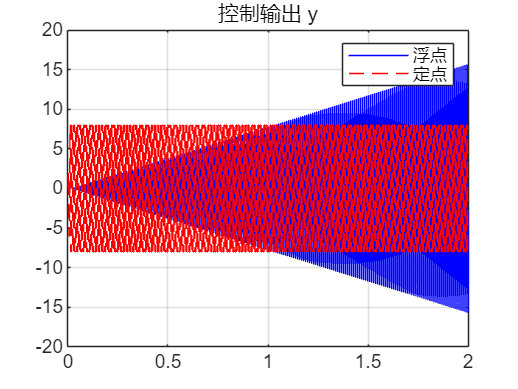


figure;
plot(t, y_f, 'b', t, y_fixed, 'r--');
legend('浮点','定点');
title('控制输出 y');
grid on;